% 目的：Flexural wave propagation in beams with periodically attached vibration absorbers: Band-gap behavior and band formation mechanisms
% Figure 3
% 
% 状态：成功复现FRF曲线
% ================================================

## 参数设置

clear;clc


%% 1. 几何参数 (Table 1)
geometry.h = 0.015;      % 梁高度 [m]
geometry.l = 0.01;       % 间距 [m]
geometry.r1 = 0.013;     % 内半径 [m]
geometry.r2 = 0.015;     % 中间半径 [m]
geometry.r3 = 0.018;     % 外半径 [m]
geometry.ucL = 0.1;      % 单元长度 [m]
geometry.N = 6;          % 单元个数
geometry.L = geometry.ucL * geometry.N;        % 梁总长度 [m]


%% 2. 材料参数 (Table 2)
% 铝层参数
material.aluminum.E = 7e10;          % 杨氏模量 [Pa]
material.aluminum.G = 2.7e10;        % 剪切模量 [Pa]
material.aluminum.rho = 2700;        % 密度 [kg/m^3]

% 橡胶层参数
material.rubber.E = 7.748e5;         % 杨氏模量 [Pa]
material.rubber.G = 2.6e5;           % 剪切模量 [Pa]
material.rubber.rho = 1300;          % 密度 [kg/m^3]

% 铜层参数
material.copper.E = 1.65e11;         % 杨氏模量 [Pa]
material.copper.G = 7.53e10;         % 剪切模量 [Pa]
material.copper.rho = 8700;          % 密度 [kg/m^3]

%% 3. 截面特性计算
% 梁的横截面积
geometry.A = pi*(geometry.r3^2-geometry.r2^2);
% 梁的惯性矩
geometry.I = pi*(geometry.r3^4-geometry.r2^4)/4;

%% 4. DVA参数计算
% 形状参数 S = l / [(r1 + r2) * ln(r2/r1)]
geometry.DVA.S = geometry.l / ((geometry.r1 + geometry.r2) * log(geometry.r2/geometry.r1));

% DVA质量 m = ρ_Cu * π * （r3²-r2²） * h
material.DVA.m = material.copper.rho * pi * (geometry.r1^2) * geometry.h;

% DVA弹簧刚度 k = [π(5 + 3.29S²)Gl] / ln(r₂/r₁)
material.DVA.k = (pi * (5 + 3.29*geometry.DVA.S^2) * material.rubber.G * geometry.l) / ...
             log(geometry.r2/geometry.r1);







## 计算和结果


%% 频率扫描范围
omega_values = linspace(1, 12000, 1000);
fre_values = omega_values ./ (2*pi());  % 转换为Hz
T_N_results = zeros(size(omega_values)); % 存储透射率结果

%% 主循环
for i = 1:length(omega_values)
    omega = omega_values(i);
    
    % 计算当前频率下的透射率
    T_N = calculate_transmission_rate(omega, material, geometry);
    % 转换为分贝(dB)：T_N(dB) = 20*log10(|T_N|)
    % T_N_results(i) = T_N;
    T_N_results(i) = 20 * log10(abs(T_N));

end

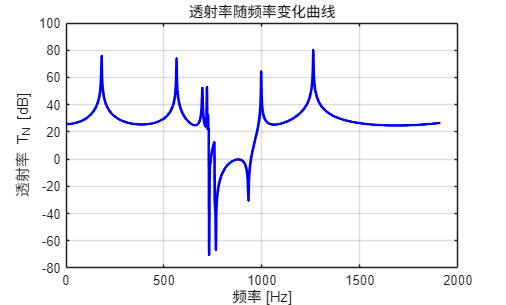


%% 绘制结果
figure;
plot(fre_values, T_N_results, 'b-', 'LineWidth', 2);
xlabel('频率 [Hz]');
ylabel('透射率 T_N [dB]');
title('透射率随频率变化曲线');
grid on;
xlim([0 2000]);

function T_N = calculate_transmission_rate(omega, material, geometry)
    % 构建全局矩阵系统
    % 输入参数：
    %   material : 材料参数结构体
    %   geometry : 几何参数结构体
    %   omega : 角频率 [rad/s]
    %
    % 输出参数：
    %   T_N : 透射率

    % 计算DVA动态刚度
    D0 = calculate_DVA_stiffness(omega, material);

    % 单元长度
    geometry.ucL;
    % La和Lb段单元长度
    La = geometry.ucL/2;  % 假设La和Lb各占一半长度
    Lb = geometry.ucL/2;

    % 计算单元矩阵（La和Lb段）
    D_La = spectral_element_matrix(omega, material, geometry, La);
    D_Lb = spectral_element_matrix(omega, material, geometry, Lb);
    
    % 提取子矩阵块
    D_LL = D_La(1:2,1:2);       % D11(La)
    D_LI = D_La(1:2,3:4);       % D12(La)
    D_IL = D_La(3:4,1:2);       % D21(La)
    D_II_La = D_La(3:4,3:4);    % D22(La)
    
    D_II_Lb = D_Lb(1:2,1:2);    % D11(Lb)
    D_IR = D_Lb(1:2,3:4);       % D12(Lb)
    D_RI = D_Lb(3:4,1:2);       % D21(Lb)
    D_RR = D_Lb(3:4,3:4);       % D22(Lb)

    % 凝聚矩阵
    % 计算公共逆矩阵项
    D_II = D_II_La + D_II_Lb + [D0 0; 0 0];
    inv_D_II = inv(D_II);

    D_LL_ = D_LL - D_LI * inv_D_II * D_IL;
    D_LR_ = -D_LI * inv_D_II * D_IR;
    D_RL_ = -D_RI * inv_D_II * D_IL;
    D_RR_ = D_RR - D_RI * inv_D_II * D_IR;

    % 构建广义特征值问题矩阵
    A = [D_RL_, D_RR_;
         zeros(2), eye(2)];
    B = [-D_LL_, -D_LR_;
         eye(2), zeros(2)];

    % 求解广义特征值问题
    [eigenvectors, eigenvalues] = eig(A, B, 'vector');
    eigenvectors = eigenvectors (1:2,:);
    mu = log(eigenvalues);

    % 识别互为倒数的特征值对
    pairs = zeros(4,1); % 存储配对索引
    tolerance = 5e-3;   % 容差，用于判断是否为倒数
    

% % 寻找共轭对
% conjugate_pairs = {};
% remaining_values = mu;
% 
% while ~isempty(remaining_values)
%     current_val = remaining_values(1);
% 
%     % 寻找其共轭复数
%     conjugate_val = conj(current_val);
% 
%     % 在剩余值中查找共轭复数
%     idx = find(abs(remaining_values - conjugate_val) < 1e-10);
% 
%     if ~isempty(idx)
%         conjugate_pairs{end+1} = [current_val, conjugate_val];
%         remaining_values([1, idx(1)]) = [];
%     else
%         conjugate_pairs{end+1} = current_val;
%         remaining_values(1) = [];
%     end
% end
% 
% % 显示分组结果
% for i = 1:length(conjugate_pairs)
%     fprintf('第%d组: ', i);
%     disp(conjugate_pairs{i});
% end

    % % 寻找成对特征值
    % for i = 1:4
    %     if pairs(i) == 0 % 如果该特征值还未配对
    %         for j = i+1:4
    %             a=real(mu(i)); b=real(mu(j));
    %             ab = abs (a + b);
    %             c=imag(mu(i)); d=imag(mu(j));
    %             cd1 = abs (c + d);
    %             cd2 = abs (c - d);
    %             if ab < tolerance && (cd1 < tolerance || cd2 < tolerance)
    %                 pairs(i) = j;
    %                 pairs(j) = i;
    %                 break;
    %             end
    %         end
    %     end
    % end

    % 寻找成对特征值
    for i = 1:4
        if pairs(i) == 0 % 如果该特征值还未配对
            for j = i+1:4
                current_val = mu(i);
                conjugate_val = mu(j);
                result = current_val + conjugate_val;
                if abs(conjugate_val + current_val) < tolerance ...
                        || (imag(conjugate_val + current_val) == 2*pi())
                    pairs(i) = j;
                    pairs(j) = i;                
                    break;
                end
            end
        end
    end

    % 确保找到两对互为倒数的特征值
    if sum(pairs == 0) > 0
        fprintf('\n=== 特征值配对错误 ===\n');
        fprintf('当前频率: omega = %.3f rad/s (%.3f Hz)\n', omega, omega/(2*pi));
    end
    
    % 重新排序特征值和特征向量
    sorted_indices = zeros(4,1);
    count = 1;
    % 找出能量流大于0的特征值（正波）放在前两位
    for i = 1:4
        phi_u = eigenvectors(:, i);
        phi_f = (D_LL_ + exp(-mu(i)) * D_LR_) * phi_u;
        phi_f_conj = conj(phi_f);
        energy_flow = 1i * omega * (phi_f_conj' * phi_u);
        if (isreal(mu(i)) && real(mu(i)) > 0 && count <= 2) ...
                || (real(energy_flow) >0 && count <= 2) ...
                || (imag(mu(i)) == pi() && real(mu(i)) > 0 && count <= 2)
            sorted_indices(count) = i;
            sorted_indices(count+2) = pairs(i);
            count = count + 1;
        end
    end

    % 重新排列特征值和特征向量
    eigenvalues_sorted = eigenvalues(sorted_indices);
    eigenvectors_sorted = eigenvectors(:, sorted_indices);
    mu_sorted = log(eigenvalues_sorted);

    % 分离正向波和反向波特征向量(位移)
    phi_u_plus  = eigenvectors_sorted(:, 1:2);   % positive wave
    phi_u_minus = eigenvectors_sorted(:, 3:4);   % negative wave


    % 计算特征向量(力)
    for j = 1:length(mu_sorted)/2
        phi_f_plus(:,j)  = (D_LL_ + exp(-mu_sorted(j)) * D_LR_) * phi_u_plus(:,j);
        phi_f_minus(:,j) = (D_LL_ + exp(mu_sorted(j)) * D_LR_) * phi_u_minus(:,j);
    end

    % 
    % % ===== 能量流正定性校验 =====
    % % 校验图片中的公式：Re(iω Φ_fj* Φ_uj) > 0
    % fprintf('\n=== 能量流正定性校验 ===\n');
    % 
    % % 检查所有特征模式
    % for j = 1:2
    %     real_part_mu = real(mu_sorted(j));
    %     % 计算复共轭
    %     phi_f_plus_conj = conj(phi_f_plus(:,j));
    %     phi_f_minus_conj = conj(phi_f_plus(:,j));
    %     % 能量流计算
    %     energy_flow_plus = 1i * omega * (phi_f_plus_conj' * phi_u_plus(:,j));
    %     energy_flow_minus = 1i * omega * (phi_f_minus_conj' * phi_u_minus(:,j));
    %     real_part_energy_plus = real(energy_flow_plus);
    %     real_part_energy_minus = real(energy_flow_minus);
    % 
    %     if real_part_mu > 0
    %         fprintf(' ✓ (满足正定性)\n');
    %     elseif  real_part_energy_plus > 0 && real_part_energy_minus > 0
    %         fprintf(' ✓ (满足正定性)\n');
    %     else
    %         fprintf(' ✗ (违反正定性)\n');
    %     end
    % end

    % E
    E_matrix = diag([exp(-mu_sorted(1)), exp(-mu_sorted(2))]);
    % 计算E^N
    E_N = E_matrix^geometry.N;
    % 构建分块矩阵U（位移关系矩阵）
    U_block = [phi_u_plus,         phi_u_minus * E_N;
               phi_u_plus * E_N,   phi_u_minus];
    % 构建分块矩阵F（力关系矩阵）
    F_block = [phi_f_plus,         phi_f_minus * E_N;
               -phi_f_plus * E_N,  -phi_f_minus];
    % 计算柔度矩阵α_N = U * F^{-1}
    alpha_N = U_block / F_block;  % 等价于 U_block * inv(F_block)

    % ===== 提取子矩阵=====
    alpha_N11 = alpha_N(1:2, 1:2);  % 左上2×2子矩阵
    alpha_N21 = alpha_N(3:4, 1:2);  % 左下2×2子矩阵

    % ===== 计算透射率T_N=====
    % 提取矩阵元素
    A11 = alpha_N11(1,1);
    B11 = alpha_N21(1,1);

    % 计算透射率 T_N = |B11 + B12 * A21 * A11^{-1}|
    % T_N = abs(B11 + B12 * A21 / A11);
    T_N = alpha_N(3,2)/ alpha_N(1,1);

end

function kb = calculate_wave_number(omega, material, geometry)
    % 计算波数kb
    % 输入参数：
    %   omega : 角频率 [rad/s]
    %   material : 材料参数结构体
    %   geometry : 几何参数结构体
    %
    % 输出参数：
    %   kb : 波数 [rad/m]
    
    kb = (material.aluminum.rho * geometry.A * omega^2 / ...
         (material.aluminum.E * geometry.I))^(1/4);
end

% 梁谱元矩阵La、Lb %
function D_beam = spectral_element_matrix(omega, material, geometry, L)
    % 输入参数：
    %   omega : 角频率 [rad/s]
    %   material : 材料参数结构体
    %   geometry : 几何参数结构体
    %
    % 输出参数：
    %   D_beam : 4×4梁刚度矩阵
    
    % 统一调用kb计算函数
    kb = calculate_wave_number(omega, material, geometry);
    kbL = kb * L;
    % 计算分母Δ
    Delta = 1 - cos(kbL)*cosh(kbL);

    % 计算各系数
    alpha = (cos(kbL)*sinh(kbL) + sin(kbL)*cosh(kbL)) * (kbL)^3 / Delta;
    alpha_bar = (sin(kbL) + sinh(kbL)) * (kbL)^3 / Delta;
    beta = (-cos(kbL)*sinh(kbL) + sin(kbL)*cosh(kbL)) * kbL / Delta;
    beta_bar = (-sin(kbL) + sinh(kbL)) * kbL / Delta;
    gamma = (-cos(kbL) + cosh(kbL)) * (kbL)^2 / Delta;
    gamma_bar = sin(kbL)*sinh(kbL) * (kbL)^2 / Delta;

    % 构建刚度矩阵
    EI = material.aluminum.E * geometry.I;  % 弯曲刚度
    % L = geometry.L;                         % 梁长度

    D11 = (EI/L^3) * [alpha, gamma_bar*L; gamma_bar*L, beta*L^2];
    D12 = (EI/L^3) * [-alpha_bar, gamma*L; -gamma*L, beta_bar*L^2];
    D21 = D12';  % D21是D12的转置
    D22 = (EI/L^3) * [alpha, -gamma_bar*L; -gamma_bar*L, beta*L^2];

    D_beam = [D11, D12; D21, D22];
end

function D_0 = calculate_DVA_stiffness(omega, material)
    % 输入参数：
    %   omega : 频率
    %   geometry : 包含材料参数的结构体
    %
    % 输出参数：
    %   D_0 : DVA动刚度

    % 读取参数
    k = material.DVA.k;
    m = material.DVA.m;

    % 计算：
    D_0 = k - k^2 / (k - omega^2 * m);
end


